# MECH 6323 - Final Project

Author: Jonas Wagner

Date: 2022-04-10

clc
clear
close all

## Plant Definition

a = 1.228;
b = 1.5618;
m = 1500;
I = 12;
% alpha_f = 0.1;
% alpha_r = 0.1;


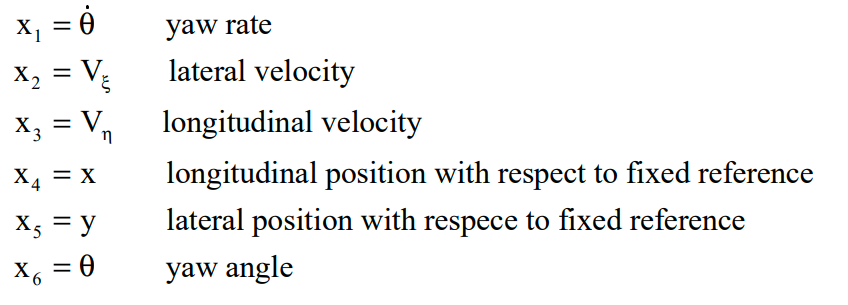

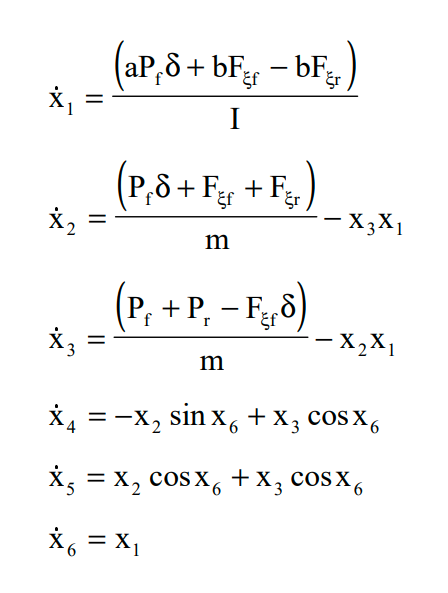

x_dot = @(x, u) [
    (a*u(2)*u(1) + b*u(4) - b*u(5))/I;
    (u(2)*u(1) + u(4) + u(5))/m - x(3)*x(1);
    (u(2) + u(3) - u(5)*u(1))/m - x(2)*x(1);
    -x(2)*sin(x(6)) + x(3)*cos(x(6));
    x(2)*cos(x(6)) + x(3)*cos(x(6));
    x(1);
];


$$x = [\dot{\theta}, V_\zeta, V_\eta, x, y, \theta]^T
$$



$$u = [\delta, P_{f}, P_{r}, F_{\zeta f}, F_{\zeta r}]^T$$


x_sym = [
    sym('theta_dot')
    sym('V_zeta')
    sym('V_eta')
    sym('x')
    sym('y')
    sym('theta')
]

$$x\_sym = \left(\begin{array}{c} \dot{\theta }\\ V_{\zeta }\\ V_{\eta }\\ x\\ y\\ \theta \end{array}\right)$$

u_sym = [
    sym('delta')
    sym('P_f')
    sym('P_r')
    sym('F_zeta_f')
    sym('F_zeta_r')
]

$$u\_sym = \left(\begin{array}{c} \delta \\ P_{f}\\ P_{r}\\ F_{\zeta ,f}\\ F_{\zeta ,r} \end{array}\right)$$

x_dot_sym = x_dot(x_sym, u_sym)

$$x\_dot\_sym = \left(\begin{array}{c} \frac{2603\,F_{\zeta ,f}}{20000}-\frac{2603\,F_{\zeta ,r}}{20000}+\frac{307\,P_{f}\,\delta }{3000}\\ \frac{F_{\zeta ,f}}{1500}+\frac{F_{\zeta ,r}}{1500}+\frac{P_{f}\,\delta }{1500}-V_{\eta }\,\dot{\theta }\\ \frac{P_{f}}{1500}+\frac{P_{r}}{1500}-\frac{F_{\zeta ,r}\,\delta }{1500}-V_{\zeta }\,\dot{\theta }\\ V_{\eta }\,\cos\left(\theta \right)-V_{\zeta }\,\sin\left(\theta \right)\\ V_{\eta }\,\cos\left(\theta \right)+V_{\zeta }\,\cos\left(\theta \right)\\ \dot{\theta } \end{array}\right)$$

## Linearize Model

This is an unrealistic thing to do outside of single time-steps

A_sym = jacobian(x_dot(x_sym,u_sym),x_sym)

$$A\_sym = \left(\begin{array}{cccccc} 0 & 0 & 0 & 0 & 0 & 0\\ -V_{\eta } & 0 & -\dot{\theta } & 0 & 0 & 0\\ -V_{\zeta } & -\dot{\theta } & 0 & 0 & 0 & 0\\ 0 & -\sin\left(\theta \right) & \cos\left(\theta \right) & 0 & 0 & -V_{\zeta }\,\cos\left(\theta \right)-V_{\eta }\,\sin\left(\theta \right)\\ 0 & \cos\left(\theta \right) & \cos\left(\theta \right) & 0 & 0 & -V_{\eta }\,\sin\left(\theta \right)-V_{\zeta }\,\sin\left(\theta \right)\\ 1 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

B_sym = jacobian(x_dot(x_sym,u_sym),u_sym)

$$B\_sym = \left(\begin{array}{ccccc} \frac{307\,P_{f}}{3000} & \frac{307\,\delta }{3000} & 0 & \frac{2603}{20000} & -\frac{2603}{20000}\\ \frac{P_{f}}{1500} & \frac{\delta }{1500} & 0 & \frac{1}{1500} & \frac{1}{1500}\\ -\frac{F_{\zeta ,r}}{1500} & \frac{1}{1500} & \frac{1}{1500} & 0 & -\frac{\delta }{1500}\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

A = @(x_0, u_0) double(subs(subs(A_sym,x_sym,x_0),u_sym,u_0));
B = @(x_0, u_0) double(subs(subs(B_sym,x_sym,x_0),u_sym,u_0));

x_0 = zeros(6,1);
u_0 = zeros(5,1);

sys_lti = ss(A(x_0,u_0), B(x_0,u_0), eye(6), 0)

sys_lti =
 
  A = 
       x1  x2  x3  x4  x5  x6
   x1   0   0   0   0   0   0
   x2   0   0   0   0   0   0
   x3   0   0   0   0   0   0
   x4   0   0   1   0   0   0
   x5   0   1   1   0   0   0
   x6   1   0   0   0   0   0
 
  B = 
              u1         u2         u3         u4         u5
   x1          0          0          0     0.1301    -0.1301
   x2          0          0          0  0.0006667  0.0006667
   x3          0  0.0006667  0.0006667          0          0
   x4          0          0          0          0          0
   x5          0          0          0          0          0
   x6          0          0          0          0          0
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
   y2   0   1   0   0   0   0
   y3   0   0   1   0   0   0
   y4   0   0   0   1   0   0
   y5   0   0   0   0   1   0
   y6   0   0   0   0   0   1
 
  D = 
       u1  u2  u3  u4  u5
   y1   0   0   0   0   0
   y2   0   0   0   0   0
   y3   0   0   0   0   0
   

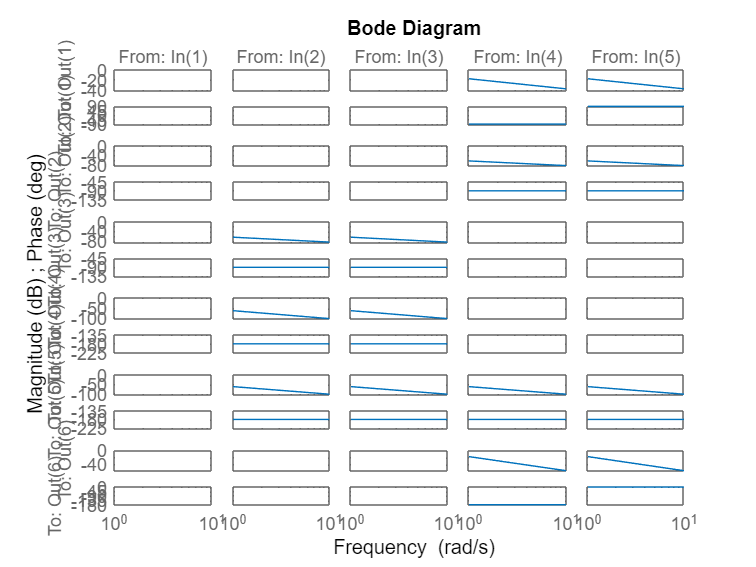

bode(sys_lti)